# Animal Movement Anlaysis - Supervised learning (SVM) 

clc; clear; close all

#### Load Data

% Data Description
% 5 videos divided into 20 frames
% x and y position of 5 body parts
load('posdata.mat') % # of video x frame x position (5 x 20 x 5)
load('frame.mat')
load('strike_labels.mat')

[nvideo, nframe] = size(posdata)

nvideo = 5

nframe = 20

% body parts : 
% 1. dorsal mantle end (mantle)
% 2. left eyes (L-eyes)
% 3. right eyes (R-eyes)
% 4. left tentacle club tips (L-tips)
% 5. Right tentacle club tips (R-tips)
bodylabels = {'mantle', 'L-eyes', 'R-eyes', 'L-tips', 'R-tips'};
[nbody, ndim] = size(posdata{1})

nbody = 5

ndim = 2

% -1 : hunting
%  1 : eating
unique( strike_labels )

ans =     -1
     1


### Check frame data & strike timing

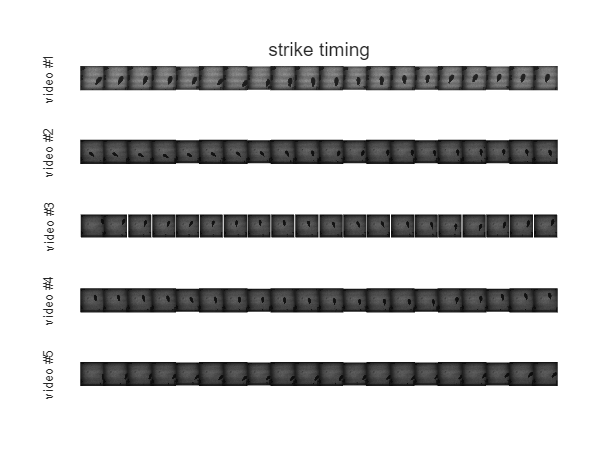

figure('WindowState', 'maximized');
ti = tiledlayout(nvideo, nframe, 'TileSpacing', 'none');
for ivid = 1: nvideo
    for ifr = 1: nframe
        nt = tilenum(ti, ivid, ifr);
        nexttile(nt);

        I(ivid, ifr) = imshow( frame{ivid, ifr} ); 
    end
    set( get( get(I(ivid, 1), 'Parent'), 'YLabel' ), 'String', ['video #' num2str(ivid)] );
end
sgtitle('strike timing')

#### Data Organization

clear pos
for ivid = 1: nvideo
    for ifr = 1: nframe
        pos(:,:, ifr, ivid) = posdata{ivid, ifr}; 
    end
end
disp( squeeze( pos(1,1,:,1) )' );

  443.6025  406.1234  400.7848  410.9282  441.8922  509.9596       NaN  470.9877  425.3425  381.8327  373.6638  337.2871  320.3978  293.1153  295.9301  325.3780  318.2326  311.7367  313.0359  315.6342



% data interpolation
fill_pos = fillmissing(pos, 'linear', 3);

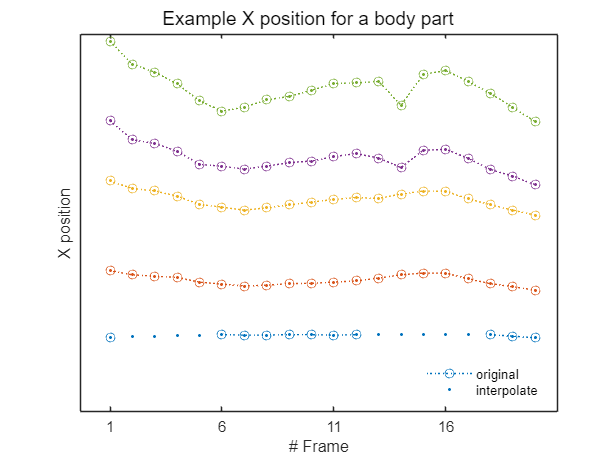

ex_vid = 5;
cb = lines(nvideo);

figure();
% original data
plt1 = plot([1:nframe], [1:nbody]'.*squeeze( pos(:,1,:,ex_vid) ), ...
        'Marker','o','LineStyle',':'); hold on;
% interpolated data
plt2 = plot([1:nframe], [1:nbody]'.*squeeze( fill_pos(:,1,:,ex_vid) ),...
        'Marker','.','LineStyle','none' );

% line color options
for i = 1: nbody
    set( plt1(i), 'Color', cb(i, :) );
    set( plt2(i), 'Color', cb(i, :) );
end
% other options
set(gca,'XTick', [1:5:20], 'YTick',[]);
xlabel('# Frame'); ylabel('X position')
xlim('padded');
legend([plt1(1) plt2(1)], {'original' 'interpolate'}, 'box', 'off', 'Location', 'southeast');
sgtitle('Example X position for a body part')

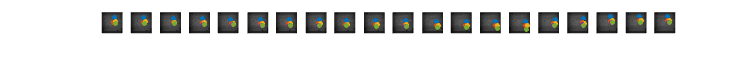

ex_vid = 4;
cb = lines(nvideo);

figure('Position', [80 640 1840 150]);
ti = tiledlayout(1, nframe, 'TileSpacing', 'none');
for ifr = 1: nframe
    nexttile();
    I(ifr) = imshow( frame{ex_vid, ifr} ); hold on;

    ax = I(ifr).Parent;
    x = fill_pos(:, 1, ifr, ex_vid );
    y = fill_pos(:, 2, ifr, ex_vid );
   
    gscatter(x, y, [1:nbody], cb, '.', 10);
    ylabel(''); xlabel('');
    legend off
end

#### SVM - Motion Classification ( BEFORE strike Vs. AFTER strike )

X = reshape( fill_pos, [], nframe*nvideo)';
y = strike_labels(:);

K = 5;
cv = cvpartition(y,'KFold',K);

clear cm_k acc_k
for k = 1: K
    idx_train = training( cv, k);
    idx_test = test( cv, k);

    feat_train = X( idx_train, :);
    lb_train = y( idx_train );

    feat_test = X( idx_test, :);
    lb_test = y( idx_test );

    % SVM training
    mdl = fitcsvm( feat_train, lb_train);

    % Prediction
    pred = predict( mdl, feat_test );
    acc_k(k) = mean( pred == lb_test );

    cm_k(:,:, k) = confusionmat( lb_test, pred );
end

Prediction result

acc = mean( acc_k )

acc = 0.8600

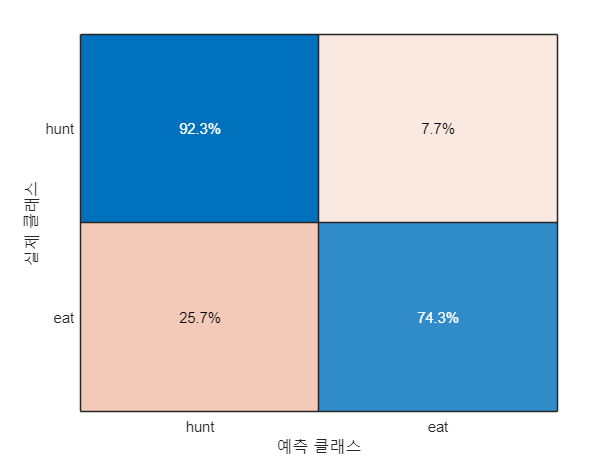

cm = sum(cm_k, 3);
labels = categorical([-1 1], [-1 1], {'hunt' 'eat'});

figure(); 
confusionchart( cm, labels, 'Normalization', 'row-normalized');

### Classification of principal components

[coeff, score, latent, ~, explained] = pca( X );
nPC = size(coeff,2)

nPC = 10

clear pc_cm_k pc_acc_k

y = strike_labels(:);
K = 5;
cv = cvpartition(y,'KFold',K);

for pc = 1: nPC
    pc_X = score(:, pc);
    for k = 1: K
        idx_train = training( cv, k);
        idx_test = test( cv, k);

        feat_train = pc_X( idx_train, :);
        lb_train = y( idx_train );
    
        feat_test = pc_X( idx_test, :);
        lb_test = y( idx_test );
    
        % SVM training
        mdl = fitcsvm( feat_train, lb_train);
    
        % Prediction
        pred = predict( mdl, feat_test );
        pc_acc_k(pc, k) = mean( pred == lb_test );
        
        % get confusion matrix
        pc_cm_k(:,:, pc, k) = confusionmat( lb_test, pred );
    end
end

Prediction result for each PC

pc_acc = mean( pc_acc_k, 2 );

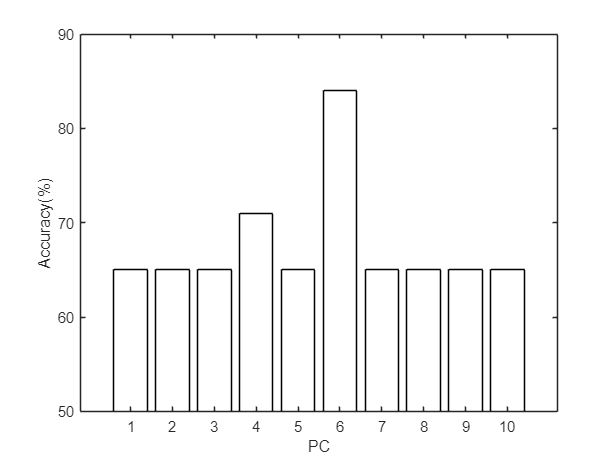

figure();
bar( [1 : nPC], pc_acc, 'FaceColor', 'none');
ylim([.5 .9]);
set(gca, 'YTick', [.5:.1:.9], 'YTickLabels', [50:10:90]);
xlabel('PC'); ylabel('Accuracy(%)')

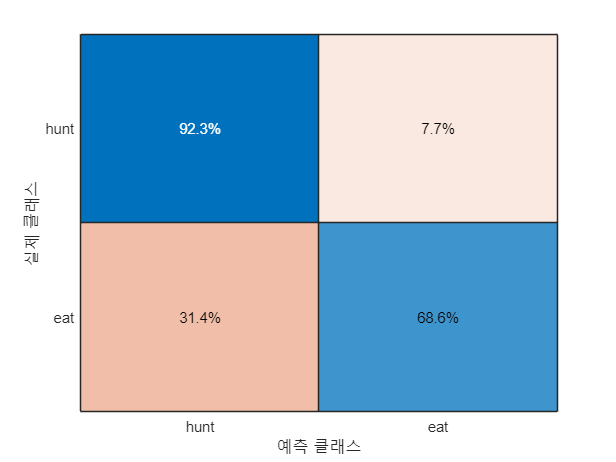

[~, idx_max_acc] = max( pc_acc );

pc_cm = sum( pc_cm_k, 4 );

labels = categorical([-1 1], [-1 1], {'hunt' 'eat'});
figure(); 
confusionchart( pc_cm(:,:,idx_max_acc), labels, 'Normalization', 'row-normalized');

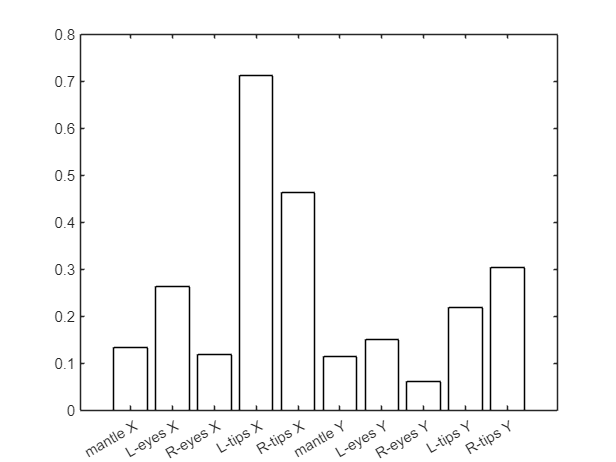

max_coeff = coeff(:, idx_max_acc);

figure();
bh = bar([ 1:length( max_coeff ) ], abs( max_coeff ), 'FaceColor', 'none' );

% set options
xticklabels = {'mantle X', 'L-eyes X', 'R-eyes X', 'L-tips X', 'R-tips X',...
    'mantle Y', 'L-eyes Y', 'R-eyes Y', 'L-tips Y', 'R-tips Y'};
set(gca, 'XTickLabels', xticklabels);

#### SVM - Body Parts Classification

pm_fill_pos = permute( fill_pos, [2,1,3,4] );
X = reshape( pm_fill_pos, [], nbody*nframe*nvideo)';
y = repmat( bodylabels', nframe, nvideo ); y = y(:);

K = 5;
cv = cvpartition(y,'KFold',K);
t = templateSVM("KernelFunction","linear");

clear body_acc_k body_cm_k
for k = 1: K
    idx_train = training( cv, k);
    idx_test = test( cv, k);

    feat_train = X( idx_train, :);
    lb_train = y( idx_train );

    feat_test = X( idx_test, :);
    lb_test = y( idx_test );

    % SVM training
    mdl = fitcecoc( feat_train, lb_train, 'Learner', t);

    % Prediction
    pred = predict( mdl, feat_test );
    body_acc_k(k) = mean( strcmp( pred, lb_test)  );
    body_cm_k(:,:, k) = confusionmat( lb_test, pred );
end
body_acc = mean( body_acc_k )

body_acc = 0.4420

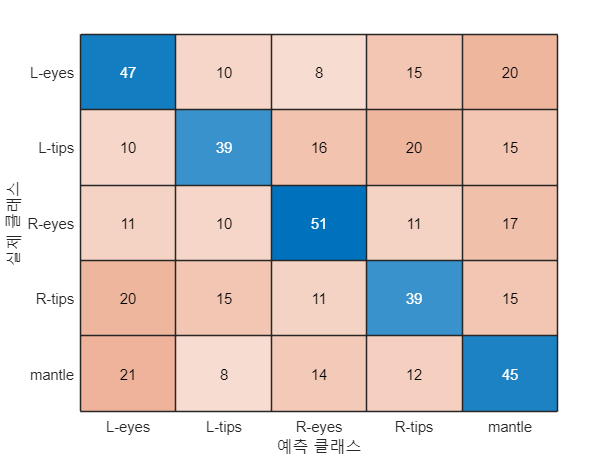

body_cm = sum(body_cm_k, 3);
figure(); confusionchart(body_cm, bodylabels);